clear all
close all
data = load('usps_all');
data = cell2mat(struct2cell(data));

%split is 90/10 throughout

## RAW DATA

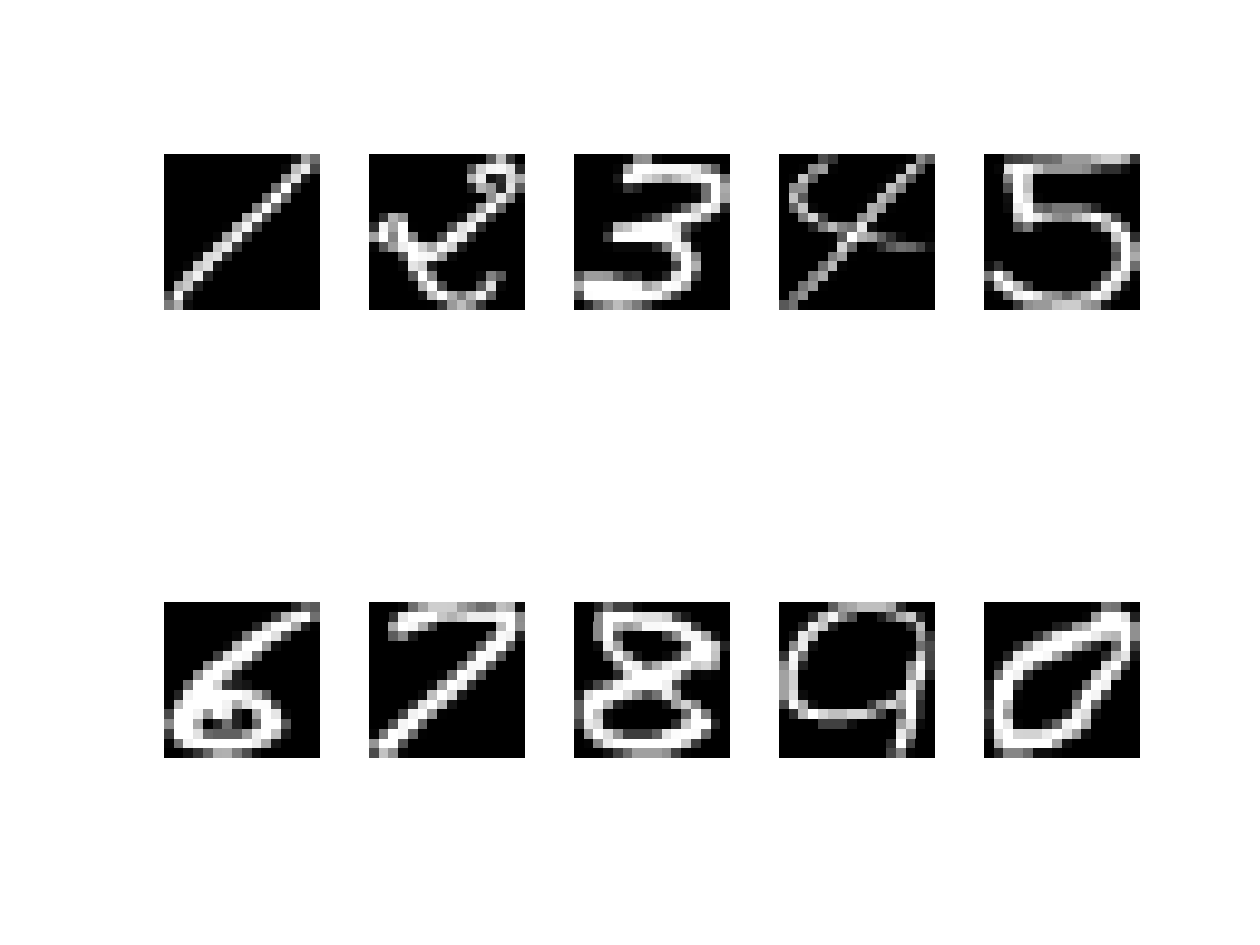

%reshaped representation of raw data
for i = 1:10
    subplot(2,5,i);
    imshow(reshape(data(:,5,i),[16 16]),[]);
end

figure;


%for i = 1:10
%    subplot(2,5,i);
%    imshow(reshape(mean(data(:,:,i),2),[16 16]),[]);
%end
%figure;
%kNN for raw data
trainset1 = [];
testset1 = [];

train_labels = [];
test_labels = [];


for i = 1:10
    if i ==10
        train_labels = [train_labels; ones(990,1)];
        test_labels = [test_labels; ones(110,1)];
    else
        train_labels = [train_labels;zeros(990,1)];
        test_labels = [test_labels; zeros(110,1)];
    end
    trainset1 = [trainset1;double(data(:,1:990,i)')];
    testset1 = [testset1;double(data(:,991:end,i)')];
end


knn = fitcknn(trainset1, train_labels,'NumNeighbors',20);
test_labels_pred = predict(knn,testset1);
accuracy = sum(test_labels == test_labels_pred)/length(test_labels);
accuracy

accuracy = 0.9927

% accuracy for raw data = 99.3% -- kNN

## PCA

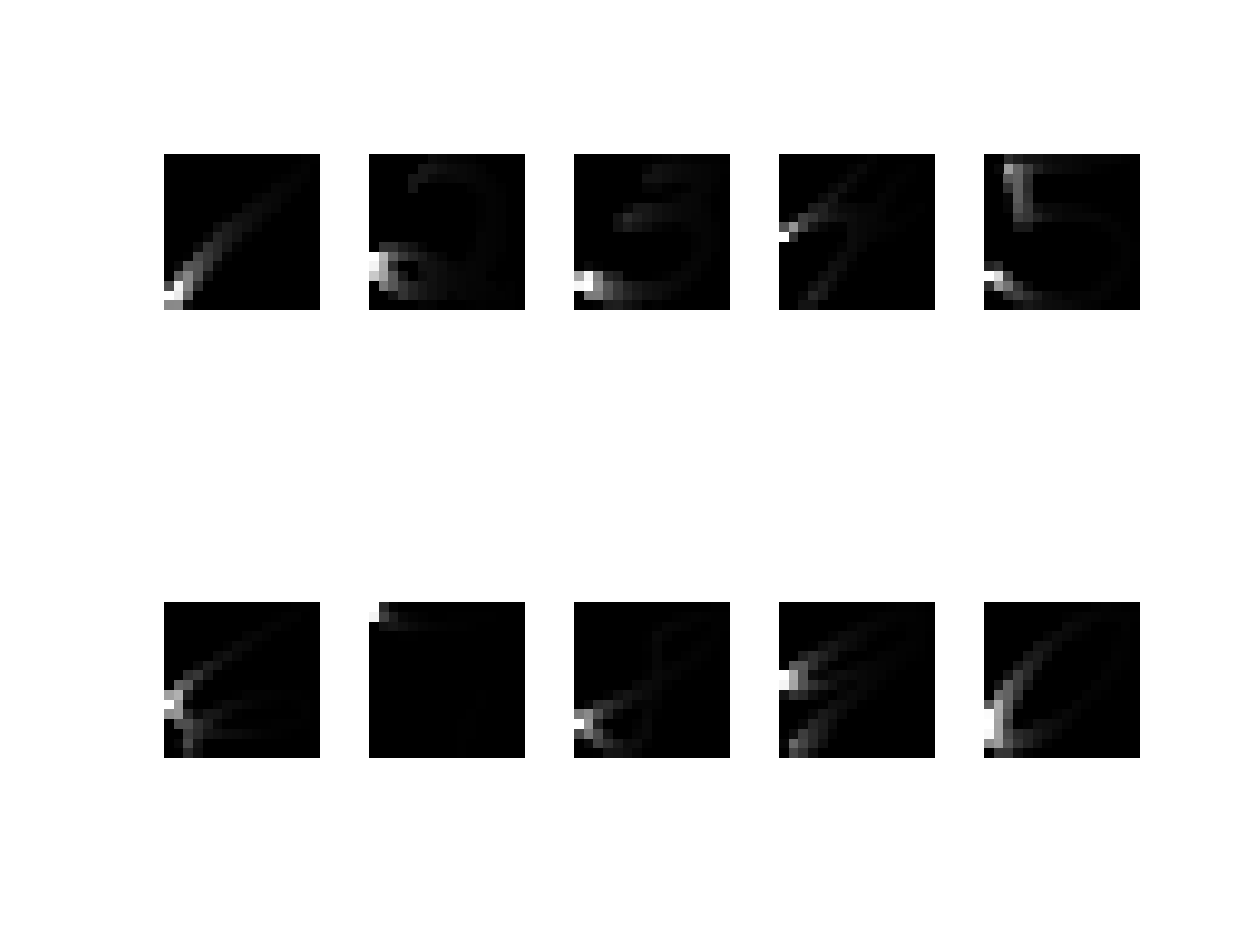


[d1, nd, nc] = size(data);
xD = zeros(d1,nd*nc);

for j = 1:d1
    auxi = data(j,:,:);
    xD(j,:) = auxi(:)';
end

[xU,xSig,xV] = svd(xD','econ');
xnPCA = 256;
%project to nPCA-dimensional space
xY = xD*xU(:,1:xnPCA);
%transforming and new data w/ PCA
xZ = xY*xD;
xnewData = xY'*xZ;
set = xnewData(:,1:1101:end);

%reshaped image representation of digits w/ PCA
for i = 1:10
    subplot(2,5,i);
    imshow(reshape(set(:,i),[16 16]),[]);
end



%kNN
[pix,d1,d2] = size(data);
X = zeros(pix,d1*d2);
d2 = 10;
ntr = 990;
ntt = d1 - ntr;
NX1 = ntr*d2;
NX2 = pix;
X = zeros(NX1,NX2);
Ntest = d2*ntt;
Xtest = zeros(Ntest,NX2);
k = 0;
ktest = 0;
for i = 1:d2
    for j = 1:ntr
        aux = data(:,j,i);
        aux = aux(:);
        k = k+1;
        X(k,:) = aux';
    end
    for j = 1:ntt
        aux = data(:,ntr+j,i);
        aux = aux(:);
        ktest = ktest+1;
        Xtest(ktest,:) = aux';
    end
end


%for j = 1:pix
%    aux = data(j,:,:);
%    X(j,:) = aux(:)';
%end

%imshow(reshape(X(:,1101),[16 16]),[]);
%to = cov(X);

[U,Sig,V] = svd(X','econ');
esort = diag(Sig); % newly added 
nPCA = 20;
Ytrain = X*U(:,1:nPCA);
Ntrain = size(Ytrain,1);
Ytest = Xtest*U(:,1:nPCA);
Ntest = size(Ytest,1);
Label_train = kron(1:d2,ones(1,ntr))';
Label_test = kron(1:d2,ones(1,ntt))';

kNN = 20;
labels = zeros(Ntest,1);
for j = 1:Ntest
    ytest = Ytest(j,:);
    dist_sq = sum((Ytrain - ones(Ntrain,1)*ytest).^2,2);
    [dsort,isort] = sort(dist_sq,'ascend');
    k_near_neib = Label_train(isort(1:kNN));
    [jclass,ja,jc] = unique(k_near_neib);
    if length(ja) < length(jc)
        labels(j) = mode(k_near_neib);
    end
end

correct = find(Label_test == labels);
accuracy = length(correct)/(Ntest);
accuracy

accuracy = 0.9355

%PCA + kNN --- 90.45% accuracy -- 256 PCA - kNN - 40
%PCA + kNN --- 92% accuracy -- 200 PCA - kNN - 20
%PCA + kNN --- 91.18% accuracy -- 100 PCA - kNN - 40
%PCA + kNN --- 93.55% accuracy -- 20 PCA - kNN - 20


## **kPCA - linear**

num_per_class = 990;
trainset2 = [];
labels = [];
testset2 = [];
train_labelsL = [];
test_labelsL = [];

%used for kPCA linear, gaussian and poly, LE
for i = 1:10
    trainset2 = [trainset2; double(data(:,1:num_per_class,i)')];
    labels = [labels; i*ones(num_per_class,1)];
end

[reduced, mapping] = compute_mapping(trainset2, 'KernelPCA',256,'linear');

 
   Welcome to the Matlab Toolbox for Dimensionality Reduction, version 0.8b (18-April-2012).
      You are free to modify or redistribute this code (for non-commercial purposes), as long as a reference
      to the original author (Laurens van der Maaten, Delft University of Technology) is retained.
      For more information, please visit http://homepage.tudelft.nl/19j49
 
Computing kernel matrix...
Eigenanalysis of kernel matrix...
Computing final embedding...


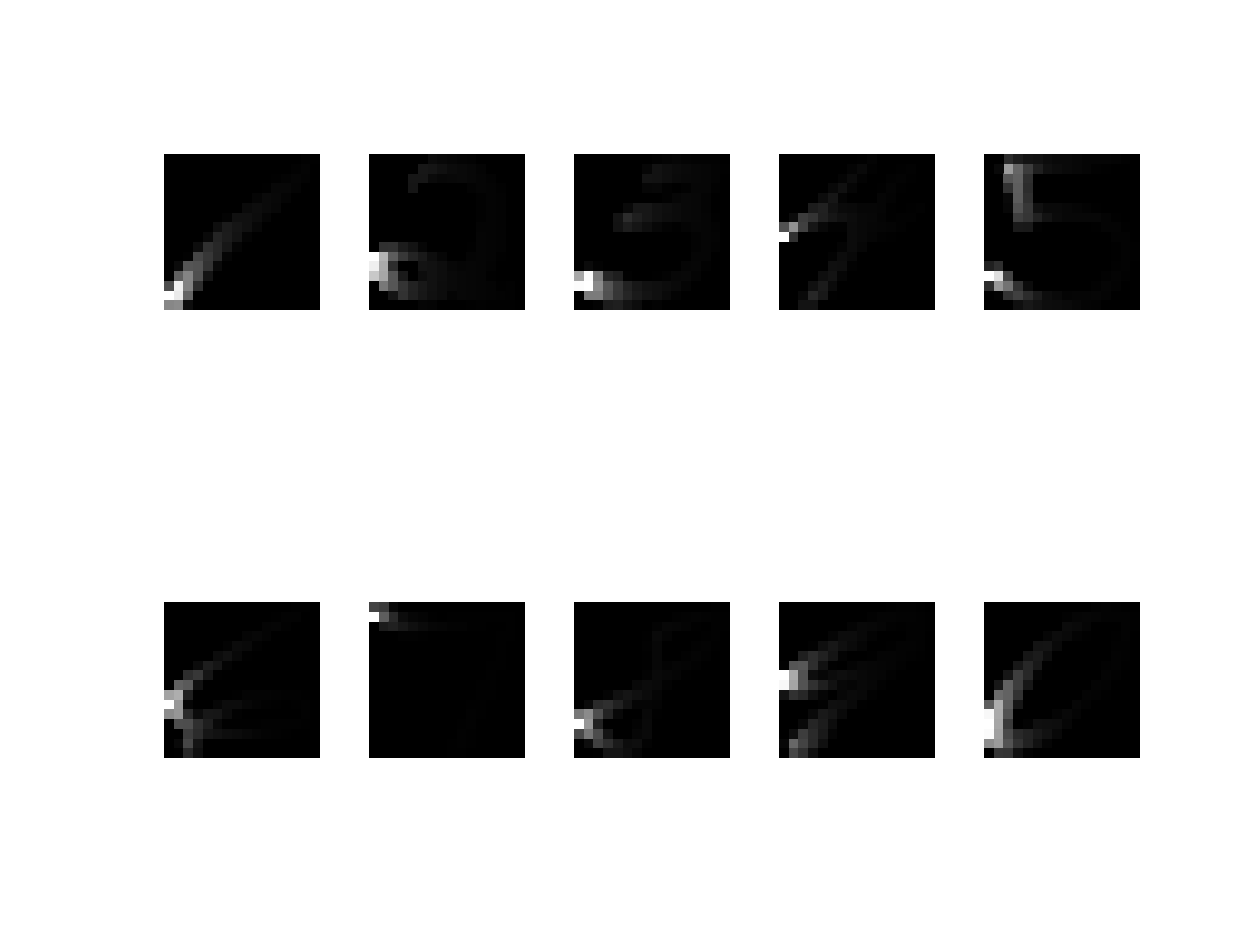


%transforming and new data w/ kPCA - linear
transformedDataLinear = reduced*xD;
decodedLinear = reduced'*transformedDataLinear;
set1 = decodedLinear(:,1:1101:end);

%showing images of new data 0-9 - %reshaped image representation of digits
%w/ kPCA - linear
for j = 1:10
    subplot(2,5,j);
    imshow(reshape(set1(:,j),[16 16]),[]);
end



%kNN - linear kPCA



%set1 = decodedLinear(:,1:1101:end);
%dataL = decodedLinear(:,)




Ntrain = 990

Ntrain = 990

Ntest = d1-Ntrain

Ntest = 110

train1 = 1:Ntrain;
train2 = (d1+1):(d1+Ntrain);
train3 = (d1+d1+1):(d1+d1+Ntrain);
train4 = (d1+d1+d1+1):(d1+d1+d1+Ntrain);
train5 = (d1+d1+d1+d1+1):(d1+d1+d1+d1+Ntrain);
train6 = (d1+d1+d1+d1+d1+1):(d1+d1+d1+d1+d1+Ntrain);
train7 =(d1+d1+d1+d1+d1+d1+1):(d1+d1+d1+d1+d1+d1+Ntrain);
train8 = (d1+d1+d1+d1++d1+d1+d1+1): (d1+d1+d1+d1+d1+d1+d1+Ntrain);
train9 = (d1+d1+d1+d1++d1+d1+d1+d1+1):(d1+d1+d1+d1+d1+d1+d1+d1+Ntrain);
train0 = (d1+d1+d1+d1++d1+d1+d1+d1+d1+1):(d1+d1+d1+d1+d1+d1+d1+d1+d1+Ntrain);

test1 = (Ntrain+1):d1;
test2 = (d1+Ntrain+1):(2*d1);
test3 = (d1+d1+Ntrain+1):(3*d1);
test4 = (d1+d1+d1+Ntrain+1):(4*d1);
test5 = (d1+d1+d1+d1+Ntrain+1):(5*d1);
test6 = (d1+d1+d1+d1+d1+Ntrain+1):(6*d1);
test7 = (d1+d1+d1+d1+d1+d1+Ntrain+1):(7*d1);
test8 = (d1+d1+d1+d1+d1+d1+d1+Ntrain+1):(8*d1);
test9 = (d1+d1+d1+d1+d1+d1+d1+d1+Ntrain+1):(9*d1);
test0 = (d1+d1+d1+d1+d1+d1+d1+d1+d1+Ntrain+1):(10*d1);


train_idx = [train1,train2,train3,train4,train5,train6,train7,train8,train9,train0];
test_idx = [test1, test2, test3, test4, test5,test6,test7,test8, test9, test0];
oYtrain = decodedLinear(:,train_idx);
oYtest = decodedLinear(:,test_idx);


train_labelsL = [train_labelsL;zeros(9900,1)];
test_labelsL = [test_labelsL;zeros(1100,1)];


testset2 = [testset2;double(data(:,991:end,i)')];

knnLinear = fitcknn(trainset2, train_idx','NumNeighbors',20);
test_labels_pred1 = predict(knnLinear,oYtest');
accuracyL = sum(test_labelsL == test_labels_pred1)/length(test_labelsL);
accuracyL

accuracyL = 0



oNtrain = size(oYtrain,1);
oNtest = size(oYtest,1);



%PCA + kNN ---   accuracy -- 256 PCA - kNN - 40
%PCA + kNN ---   accuracy -- 200 PCA - kNN - 20
%PCA + kNN ---   accuracy -- 100 PCA - kNN - 40
%PCA + kNN ---   accuracy -- 20 PCA - kNN - 20


## LE

[reduced, mapping] = compute_mapping(trainset2,'Laplacian',256);

Constructing neighborhood graph...
Computing weight matrices...
Constructing Eigenmaps...


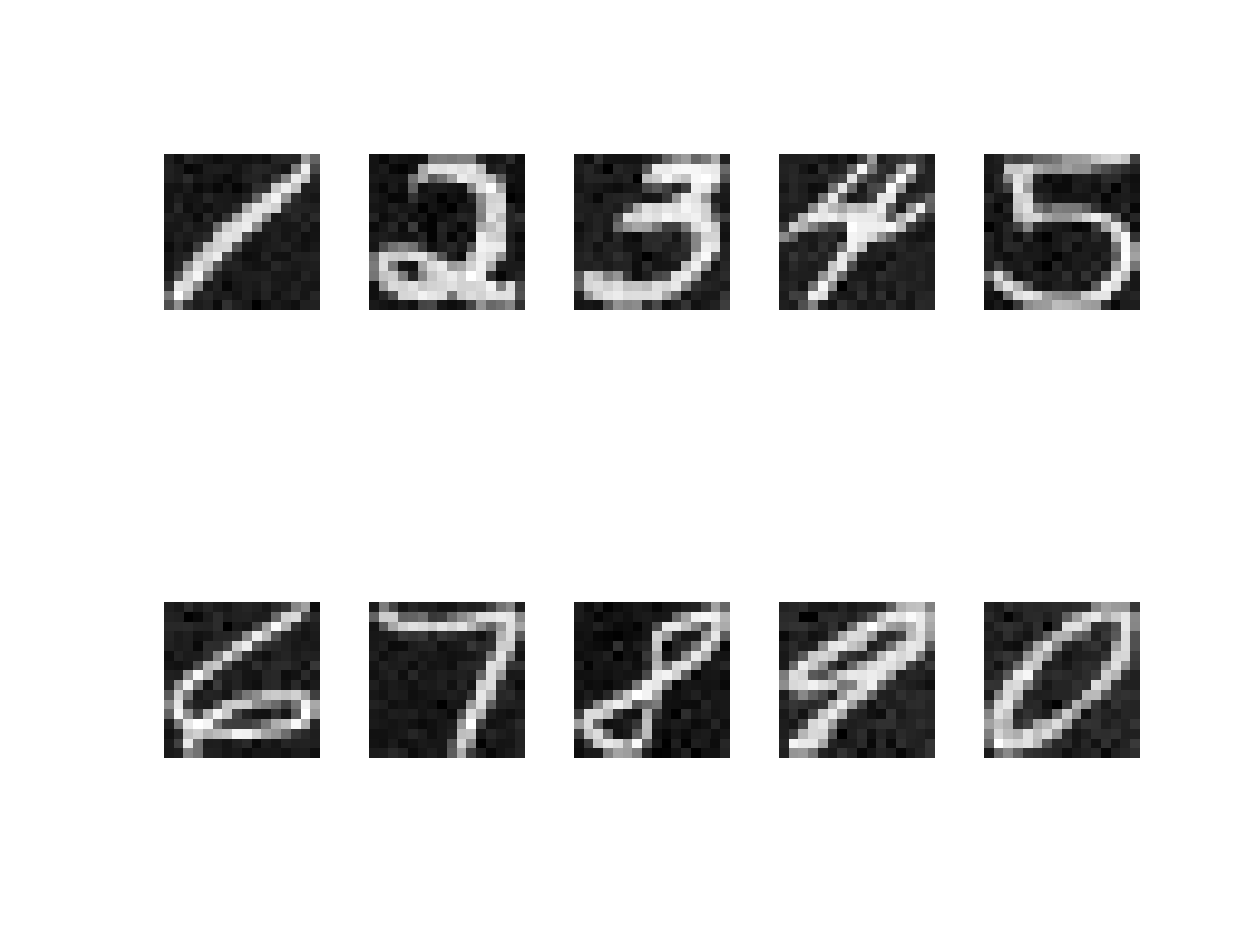

%transforming and new data w/ LE
transformedDataLE = reduced*xD;
decodedLE = reduced'*transformedDataLE;
setLE = decodedLE(:,1:1101:end);

%%reshaped image representation of digits w/ LE
for j = 1:10
    subplot(2,5,j);
    imshow(reshape(setLE(:,j),[16 16]),[]);
end

%PCA + kNN ---   accuracy -- 256 PCA - kNN - 40
%PCA + kNN ---   accuracy -- 200 PCA - kNN - 20
%PCA + kNN ---   accuracy -- 100 PCA - kNN - 40
%PCA + kNN ---   accuracy -- 20 PCA - kNN - 20





## kPCA - Gaussian

[reduced, mapping] = compute_mapping(trainset2, 'KernelPCA',256);

Computing kernel matrix...
Eigenanalysis of kernel matrix...
Computing final embedding...


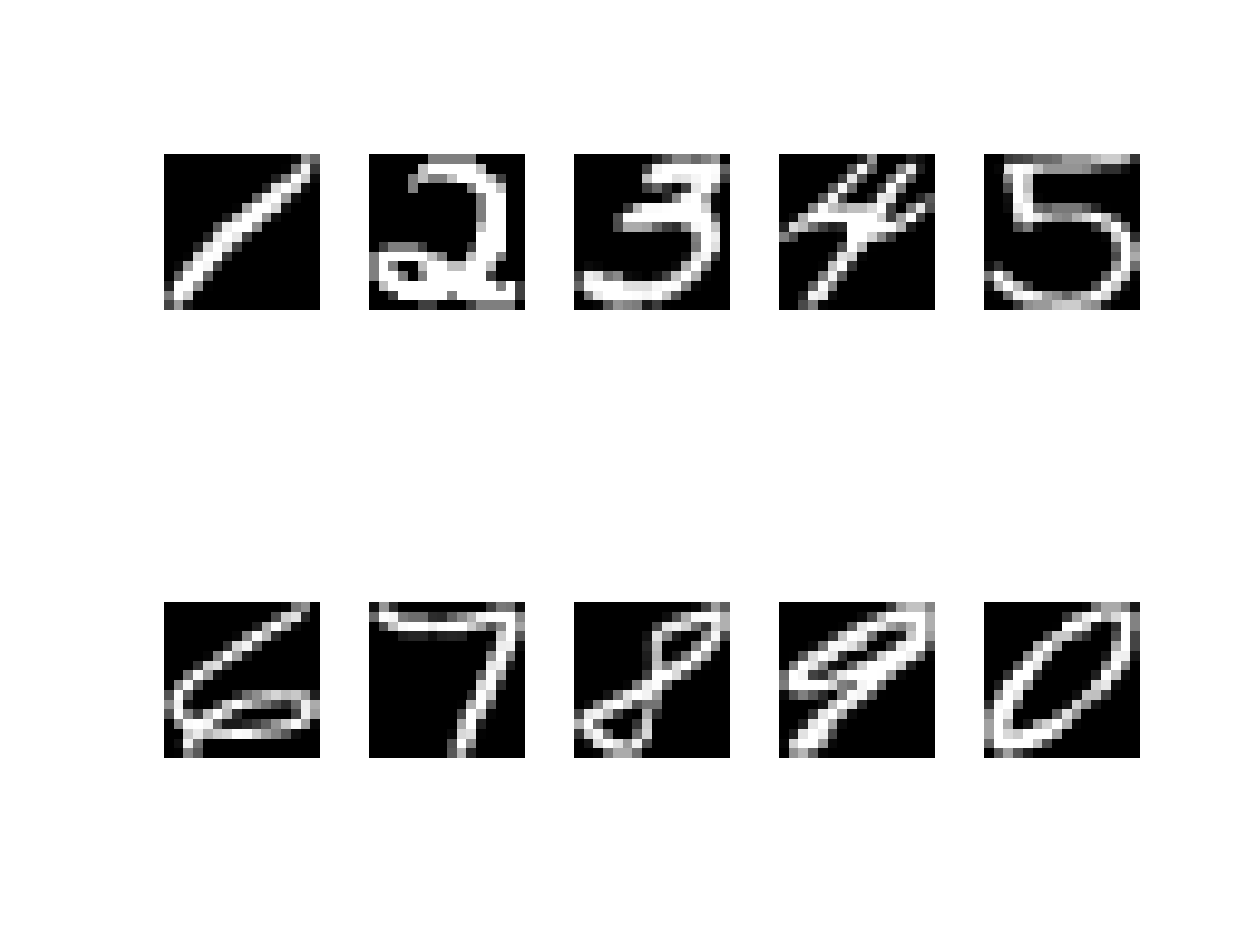



transformedDataGaussian = reduced*xD;
decodedGaussian = reduced'*transformedDataGaussian;
set2 = decodedGaussian(:,1:1101:end);

%showing images of new data 0-9
for j = 1:10
    subplot(2,5,j);
    imshow(reshape(set2(:,j),[16 16]),[]);
end

%kPCA - Poly

%[reduced, mapping] = compute_mapping(trainset, 'KernelPCA',256,'poly');

%%transformedDataPoly = reduced*X;
%decodedPoly = reduced'*transformedDataPoly;
%set3 = decodedPoly(:,1:1101:end);

%showing images of new data 0-9
%for j = 1:10
%    subplot(2,5,j);
%    imshow(reshape(set3(:,j),[16 16]),[]);
%end